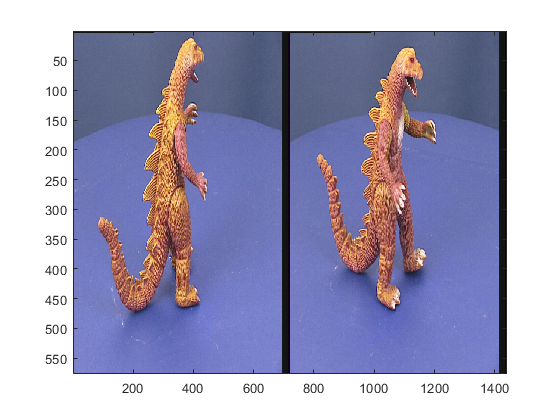

im1=imread('dinosaur0.png');
im2=imread('dinosaur5.png');
load('dino_Ps','P');
figure(1);image([im1 im2]);

C1=P{1};       % The camera matrix corresponding to image 1
C2=P{6};       % The camera matrix corresponding to image 2

n1 = null(C1);
n2 = null(C2)

n2 =    -0.4535
    0.5425
   -0.0000
    0.7071


e12 = C1*n2

e12 =    22.3733
   -4.1694
    0.0030


e21 = C2*n1;
F21 = liu_crossop(e21)*C2*pinv(C1)

F21 = 	1.0e+03 *

   -0.0000   -0.0000   -0.0031
   -0.0000    0.0000    0.0225
   -0.0041   -0.0202    2.5172


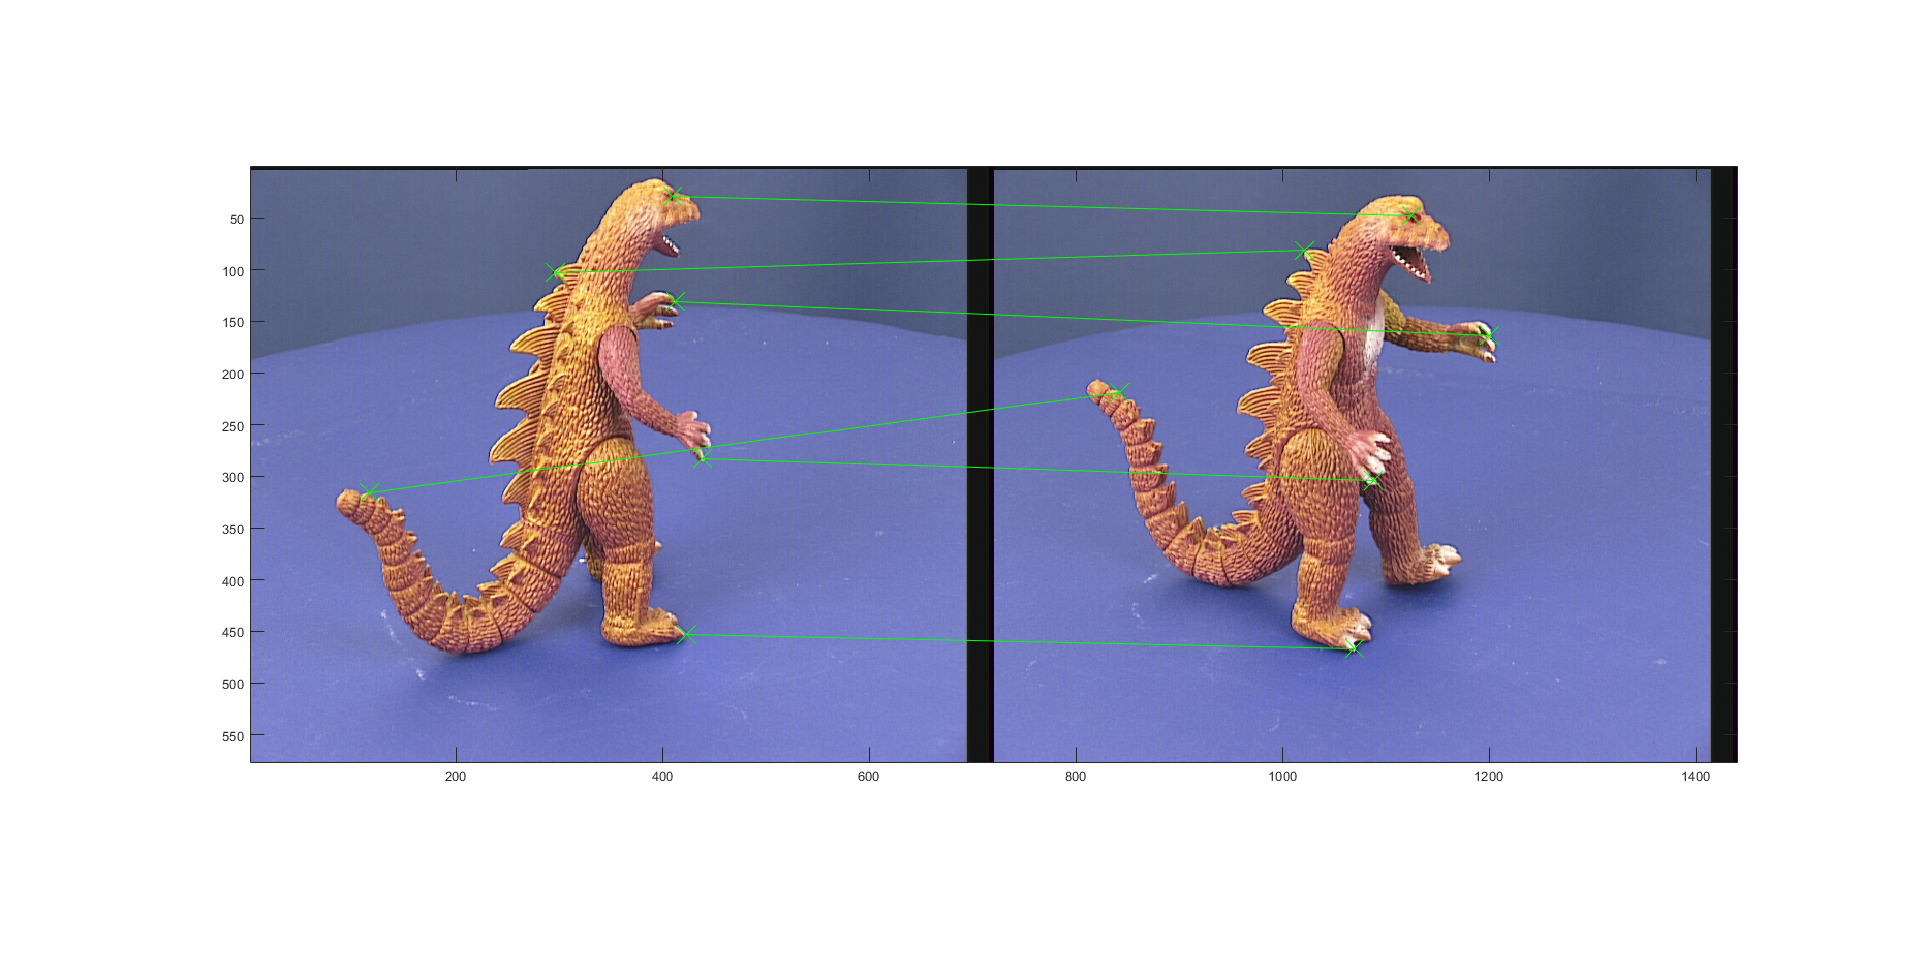

%%
[y1,y2]=correspondences_select(im1,im2);

y1(end+1,:)=1;
y2(end+1,:)=1;

%%

l2=F21*y1;
l1=F21'*y2;
for ix=1:size(y1,2),
    l1(:,ix)=-l1(:,ix)/norm(l1(1:2,ix))*sign(l1(3,ix));
    l2(:,ix)=-l2(:,ix)/norm(l2(1:2,ix))*sign(l2(3,ix));
end

figure(2);clf;
subplot(1,2,1);image(im1);hold on;
subplot(1,2,2);image(im2);hold on;
for k=1:size(y1,2),
    subplot(1,2,1);plot(y1(1,k),y1(2,k), 'r*');drawline(l1(:,k));
    subplot(1,2,2);plot(y2(1,k),y2(2,k), 'r*');drawline(l2(:,k));
end

%%
e12_norm = e12/e12(3)

e12_norm = 	1.0e+03 *

    7.3908
   -1.3773
    0.0010


e21_norm = e21/e21(3)

e21_norm = 	1.0e+03 *

   -6.4174
   -0.9879
    0.0010



abs(sum(y1.*l1))

ans =     2.3874    2.4722    0.9297    1.5533    1.9814    2.0395


abs(sum(y2.*l2))

ans =     2.4310    2.4388    0.8697    1.5770    1.9994    2.0993



e12_line = cross(l1(:,1),l1(:,2))

e12_line =   -50.6796
    9.4444
   -0.0069


e12_line = e12_line/e12_line(3)

e12_line = 	1.0e+03 *

    7.3908
   -1.3773
    0.0010



e21_line = cross(l2(:,1),l2(:,2))

e21_line =    46.2866
    7.1251
   -0.0072


e21_line = e21_line/e21_line(3)

e21_line = 	1.0e+03 *

   -6.4174
   -0.9879
    0.0010



%%
w=720;h=576; % Image width and height
lambda = -5:0.01:5; %Replace with the interval you choose
dist = LoopZhangDistortion(e12,e21,w,h,lambda);
figure(3);plot(lambda,dist);
set(gca,'YScale','log');grid on;
lmin = lambda(dist==min(dist)) %Print minimum lambda

lmin = -1.2500


%%
lambda = -1.25   % Insert your value here

lambda = -1.2500

w1=liu_crossop(e12)*[lambda 1 0]';
w1=w1/w1(3);
w2=F21*[lambda 1 0]';
w2=w2/w2(3);
Hp1=[1 0 0;0 1 0;w1'];
Hp2=[1 0 0;0 1 0;w2'];

%%
vcp=0;
Hr1=[F21(3,2)-w1(2)*F21(3,3) w1(1)*F21(3,3)-F21(3,1) 0;
F21(3,1)-w1(1)*F21(3,3) F21(3,2)-w1(2)*F21(3,3) F21(3,3)+vcp;
0 0 1];
Hr2=[w2(2)*F21(3,3)-F21(2,3) F21(1,3)-w2(1)*F21(3,3) 0;
w2(1)*F21(3,3)-F21(1,3) w2(2)*F21(3,3)-F21(2,3) vcp;
0 0 1];

flip_matrix = [ -1 0 0;
                0 -1 0;
                0 0 1]

flip_matrix =     -1     0     0
     0    -1     0
     0     0     1



H1 = flip_matrix*Hr1*Hp1;
H2 = flip_matrix*Hr2*Hp2;

Fr = inv(H2)'*F21*inv(H1)

Fr =    -0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000   -1.0000    0.0000



%%

oldcorners=[1 w w 1;1 1 h h];
newcorners1=map_points(H1,oldcorners);
newcorners2=map_points(H2,oldcorners);
mincol=min([newcorners1(1,:) newcorners2(1,:)]);
minrow=min([newcorners1(2,:) newcorners2(2,:)]);
T=[1 0 -mincol+1;0 1 -minrow+1;0 0 1]

T = 	1.0e+03 *

    0.0010         0    2.3969
         0    0.0010    2.4948
         0         0    0.0010


newcorners1=map_points(T*H1,oldcorners);
newcorners2=map_points(T*H2,oldcorners);
maxcol=max([newcorners1(1,:) newcorners2(1,:)]);
maxrow=max([newcorners1(2,:) newcorners2(2,:)]);
inv_T=inv(diag([maxcol/w maxrow/h 1]))

inv_T =     0.0338         0         0
         0    0.0308         0
         0         0    1.0000


T=inv(diag([maxcol/w maxrow/h 1]))*T

T =     0.0338         0   81.0435
         0    0.0308   76.8540
         0         0    1.0000



%%

imr1=image_resample(double(im1),T*H1,h,w);
imr2=image_resample(double(im2),T*H2,h,w);
figure(5);image(uint8([imr1 imr2]));hold on;

y2_trans = map_points(T*H2,y2(1:2,:))

y2_trans =   383.5379  317.7562  207.1346  408.0926  429.3612  457.5108
   66.9914  100.9791  224.5139  254.6560  387.8600  137.7992


y1_trans = map_points(T*H1,y1(1:2,:))

y1_trans =   372.5490  280.1363  122.9375  379.1467  353.6851  368.1192
   68.6320  102.6939  223.8263  255.8849  389.5757  139.2769



for k=1:size(y1_trans,2),
    plot(y1_trans(1,k),y1_trans(2,k), 'r*');
    plot(y2_trans(1,k)+720,y2_trans(2,k), 'r*');
    plot([y1_trans(1,k) y2_trans(1,k)+720], [y1_trans(2,k) y2_trans(2,k)])
end
%%

%[y1,y2]=correspondences_select(im1,im2);
%y1(end+1,:)=1;
%y2(end+1,:)=1;
%%
F = fmatrix_n8pa(y1,y2)
%%
figure(6);clf;
subplot(1,2,1);image(im1);hold on;
subplot(1,2,2);image(im2);hold on;

l2_8p=F*y1;
l1_8p=F'*y2;

for k=1:size(y1,2),
    l1_8p(:,k)=-l1_8p(:,k)/norm(l1_8p(1:2,k))*sign(l1_8p(3,k)); %Normalise dual
    l2_8p(:,k)=-l2_8p(:,k)/norm(l2_8p(1:2,k))*sign(l2_8p(3,k)); %homog. coord.
end

for k=1:size(y1,2),
    subplot(1,2,1);plot(y1(1,k),y1(2,k),'or');drawline(l1_8p(:,k));
    subplot(1,2,2);plot(y2(1,k),y2(2,k),'or');drawline(l2_8p(:,k));
end
dist_im1_8p = mean(abs(sum(y1.*l1_8p)))
dist_im2_8p = mean(abs(sum(y2.*l2_8p)))


dist_im1 = mean(abs(sum(y1.*l1)))
dist_im2 = mean(abs(sum(y2.*l2)))
